data_root_dir = '/home/linux-pc/gh/V1-Visual-Cortex-Visualization/data/crcns-pvc1/crcns-ringach-data/';
neuro_root_dir = 'neurodata/ac1/';
movie_root_dir = 'movie_frames/movie000_000.images/';
current_movie = "movie000_000_000.jpeg";
current_neuro_data = "ac1_u004_000.mat";

load_img = strcat(data_root_dir, movie_root_dir, current_movie)

load_img = "/home/linux-pc/gh/V1-Visual-Cortex-Visualization/data/crcns-pvc1/crcns-ringach-data/movie_frames/movie000_000.images/movie000_000_000.jpeg"

%if ~strcmp(str1, str2)
%    disp('Strings are different');
%end

load_str = "/home/linux-pc/gh/V1-Visual-Cortex-Visualization/data/crcns-ringach-data/movie_frames/movie000_000.images/movie000_000_000.jpeg"

imread(load_img)

ans = 240×320×3 uint8 array
ans(:,:,1) =

    81    63    70    76    68    81    89    61    57    56    50    53    51    57    24    25    13    15    16    14    10     6     4     5    14    15    17    20    23    23    21    19    14    10     4     0     0     2     7    11     3    11    19    16     6     0     0     0     0     0     2     4     6     8     9    10     3     2     0     0     0     0     2     3     7     7     8     7     5     2     0     0     0     0     0     3     6     8     9    10     4     3     1     0     0     0     0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     7     0     8    16    28    23    68    78    67    79    69    77    65    81    64    56    65    66    64    65    66    67    66    67    64    63    63    62    61    60    59    59    63    62    60    58    57    57    58    59    64    66    68    70    70    69    68    66    68    68    68    68    68    69    69    

neuro_str = strcat(data_root_dir, neuro_root_dir, current_neuro_data);

load(neuro_str)

pepANA.listOfResults{1}

ans = struct with fields:
    condition: [0 0 0 0 0]
      symbols: {'movie_id'  'segment_id'}
       values: {[0]  [0]}
    noRepeats: 1
       repeat: {[1×1 struct]}


## Total Number of Conditions

pepANA.no_conditions

ans = 120

## Arrival Times for electrodes in pepANA.elec_list

pepANA.listOfResults{1}.repeat{1}.data{1}{1}

ans =     0.4543    0.5465    0.8413    0.8919    1.0303    1.0468    1.0921    1.0955    1.0975    1.1127    1.1340    1.1364    1.1461    1.1505    1.1536    1.1659    1.1676    1.1728    1.1845    1.1907    1.1957    1.2081    1.2114    1.2207    1.2462    1.3205    1.7505    1.7624    2.0124    2.0194    2.6703    2.8907    2.9705    3.1544    3.2081    3.2501    3.8376    3.8666    3.8696    3.8726    3.8750    3.8808    3.8824    3.8884    3.8904    3.8929    3.8959    3.9338    3.9362    3.9381


## Detected Waveforms at that time (48 samples of waveform snippets) (contains spikes and noise bc of low threshold) (1.6ms sampled at 30kHz at int8 precision)

pepANA.listOfResults{1}.repeat{1}.data{1}{2}

ans = 48×573 int8 matrix
     0    -6    -2     3    -3    -8     3     0    10    -7    -2     4    -6     3    -5     8    -8    -8    -3   -11     4   -15    -3    -8     9     2    -6    -4    -8    -1    -7     0    -9    10    -6     5    -7    -9    16    -3    20    -1   -11     9     0    -9    -3     5    -5   -16
    -1    -3    -2     2    -1     1    -3    -3    -2    -4    -3     7    -7     1    -7     5    -3    -9     1    -5     2   -18    -6   -16    -2     5   -10    -1    -7     3   -10    -1    -9     0     0     7   -13   -10     4    -7    17    -3   -17    -2     4   -14    -9     9    -8   -19
     3    -3    -2     1    -1     8    -3    -5    -8    -2     4     6    -6    -5    -7     2    -4     0     2    -1     1   -13    -4   -14    -7     4   -12    -8     1     3    -6    -5    -7    -7     2     5   -14    -5     3     5    18     2   -12    -7     7    -7   -12     4    -7   -11
     1    -3    -3     1    -3     6     1    -6    -2    -3     1     3

## Electrodes

pepANA.elec_list

ans =      5     6    10    13    15    22    23    26    38    46    47    54    55    73    78    85


## Examining Waveforms

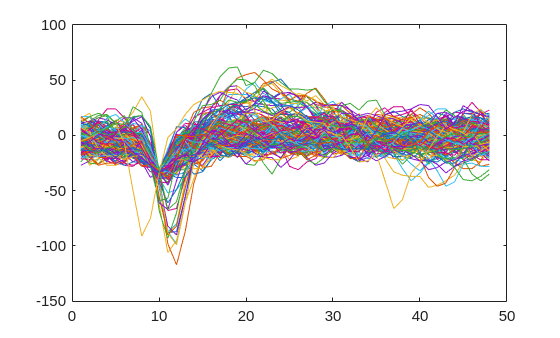

q = pepANA.listOfResults{1}.repeat{1}.data{13}{2};
plot(q)

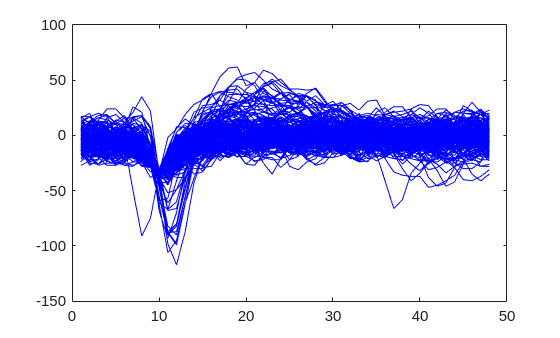

figure(gcf)
plot(q, "b")

## SVD of Waveforms

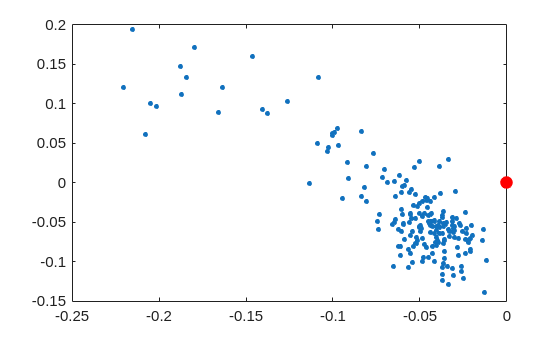

[u, s, v] = svd(double(q));
plot(v(:, 1), v(:, 2), '.', 'markersize', 10); hold on; plot(0,0, 'r.', 'markersize', 25)

## Classifying Waveforms with K-means clustering

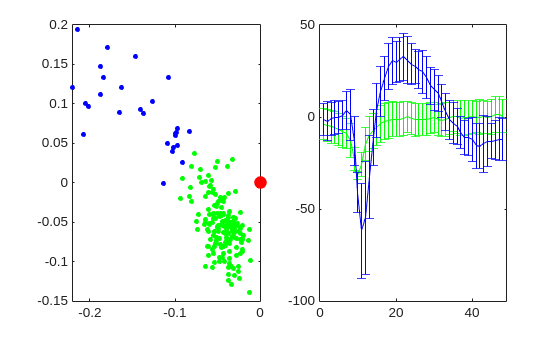

idx = kmeans(double(q'),2); %% cluster waveforms in 2 classes using k-means
idx1 = find(idx==1); idx2=find(idx==2);
subplot(1, 2, 1)
plot(v(idx1, 1), v(idx1, 2), 'b.', 'markersize',10); hold on;
plot(0, 0, 'r.', 'markersize', 25); plot(v(idx2, 1), v(idx2, 2), 'g.', 'markersize', 10);
subplot(1, 2, 2)
errorbar(1:size(q,1), mean(double(q(:, idx2)'),1), std(double(q(:, idx2)'),[],1), 'g'); hold on;
errorbar(1:size(q,1), mean(double(q(:, idx1)'),1), std(double(q(:, idx1)'),[],1), 'b');

xlim([0 49])


% set(gcf, 'Renderer', 'painters'); % or 'opengl'
